# Honours Live Script 3

## Load and Save Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

if exist("workspaceVarHonours", 'var')
    clearVarsArray = clearVars();
    clear(clearVarsArray{:})
    clear clearVarsArray
    save matlabHonours.mat
end 

% set the default intepreter to latex
setInterpLatex()

## Contents

Coral Trout Experiment Parameter Setting

Preliminary Coral Trout Simulations (Uniform Areas)

Improving Mike's Code

Loading Final CT Data and Matching to Shapefile

## Assumptions Made

% all the parameters for the coral trout model for the connectivity
% surrogates paper by Mike

% I got rid of the extra column in the coral trout connectivity matrices

% I am going to sort the coral trout things by latitude, and so some of
% sections may be using different data, but this only matters when making
% reef to reef comparisons

% Mike's matrices had rows of NaNs which was so totally cool and awesome,
% so I just replaced them with zeros

## Coral Trout Experiment Parameter Setting

% load in the coral trout data -> need to switch folders
load coralTroutConnectivityData.mat
centroidsCTFull = centroid;
conMatsCTOld = conMatsCoralTrout;
conMatsCTNames = conMatsCoralTroutNames;
clear centroid conMatsCoralTrout conMatsCoralTroutNames

% convert the nonzero matrices to sparse storage
nonzeroMats = zeros(1, length(conMatsCTOld));
for i = 1:length(conMatsCTOld)
    conMatsCTOld{i} = sparse(conMatsCTOld{i});
end

% something is absolutely cooked with these matrices, so I am going to
% first replace the NaNs with zeros, and then have another look at them
for m = 1:length(conMatsCTOld)

    % find the NaN values
    nanVals = isnan(conMatsCTOld{m});

    % replace them with zeros
    conMatsCTOld{m}(nanVals) = 0;
   
end

% now remove any of the unfinished matrices
unfinMats = zeros(1, length(conMatsCTOld));
for i = 1:length(conMatsCTOld)
    if sum(sum(conMatsCTOld{i})) == 0
        unfinMats(i) = 1;
    end
end
reefs = find(unfinMats > 0);

% remove the unfinished mats
conMatsCTOld = conMatsCTOld(1:(reefs(1) - 1));

% remove any rows with NaNs
nansInd = zeros(length(centroidsCTFull), 1);
for i = 1:length(centroidsCTFull)
    if sum(isnan(centroidsCTFull(i, :))) > 0
        nansInd(i) = 1;
    end
end
centroidsCTFull = centroidsCTFull(nansInd == 0, :);

% for fuck sake, the original matrices have heaps of run sums around or
% above 1 fuck me dead

% I'm going to grab COTS matrices instead then

% go back and find where massVec comes from and what it represents as it
% could be used to do the age class weightings

% gonna load in the COTS data here
gotoCOTS()
load matlabCOTS.mat SLIMCellDaily SLIMCellDailyNames
gotoHonours()

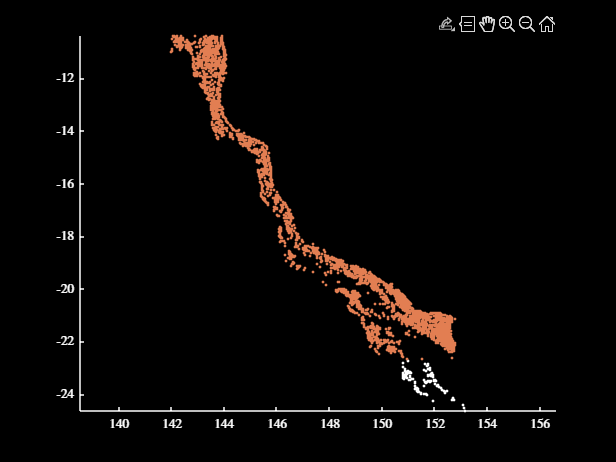

% ok cool, let's identify the reefs from that little section that Mike
% wanted, and grab the centroids for the GBRShapeLL
figure
hold on
centroidsGBRLL = zeros(length(GBRShapeLL), 2);
for r = 1:length(GBRShapeLL)
    centroidsGBRLL(r, :) = GBRShapeLL(r).Centroid;
end
test = centroidsGBRLL(:, 2) < -22.7;
plot(centroidsGBRLL(test, 1), centroidsGBRLL(test, 2), 'k.')
plot(centroidsGBRLL(~test, 1), centroidsGBRLL(~test, 2), '.')
axis equal
darkFig()

sum(test)

ans = 126


% ok so for now I'm just going to use the COTS matrices
conMatsCTPre = cell(1, length(SLIMCellDaily));
for t = 1:length(SLIMCellDaily)
    conMatsCTPre{t} = SLIMCellDaily{t}(test, test);
end

% set up the specStruct values
sizeVec = 52.2 * (1 - exp(-0.354 * (1:14 + 0.766)));
fecundVec = 13.82 * sizeVec.^3.03;
massVecCT = 0.0079 * sizeVec;
specStructCT = struct();
unifPop = repmat(100, [1, 14]);
popInit = repmat(unifPop, [length(conMatsCTPre{1}), 1]);
specStructCT.alpha = 1.5 * 10^-5;
specStructCT.beta = 1 * 10^-8;
specStructCT.successVec = cat(2, [0.6, 0.7], repmat(0.83, [1, 11]));
specStructCT.fecundVec = fecundVec;

% also need to use the areas, but for now I'm just goingto make it uniform
areasCT = ones(length(conMatsCTPre{1}), 1);

% run the simulation for a long enough period of time so that the
% populations will stabilise
tWarmup = 1000;
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsCTPre), 1, tWarmup - 1);
popInitTest = 50 * ones(length(conMatsCTPre{1}), 14);
actionStruct.type = "MPA";
popMatTest = baseMetapopModel(conMatsCTPre, areasCT, ...
        popInitTest, tWarmup, specStructCT, randStruct);

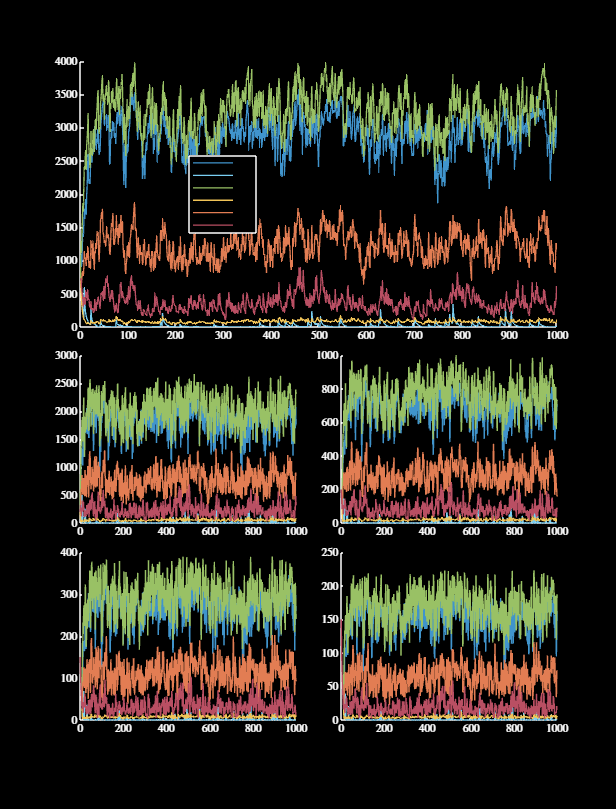

% visualise a random selection of the reefs
var1 = [1, 4, 5, 6, 78, 30];
tL = visualiseMetapop(popMatTest(var1, :, :), 1:tWarmup);
title(tL, "Coral Trout Test Run", 'Interpreter', 'Latex')
darkFig(tL)
figResize(1.75)
% saveCoolFig("CoralTroutRun2", "labelsLegend")

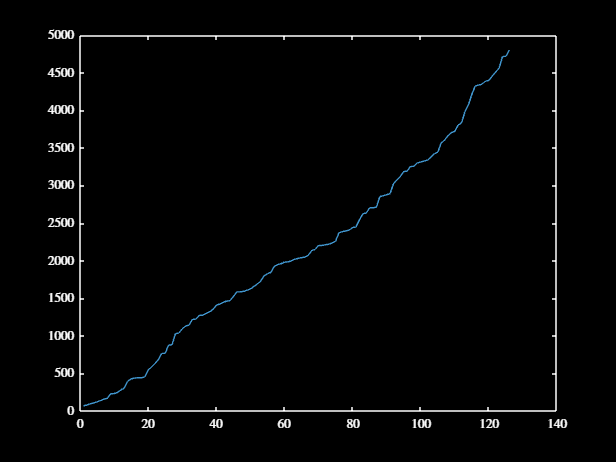

% check the number of reefs which have gone extinct
test = sum(popMatTest(:, :, end), 2);

% plot the distribution of the total populations for the reefs
figure
plot(sort(test))
darkFig()


% sweet, nothing went extinct so I'm just going to set the initial
% populations for each reef in the simulations below as the mean of the
% last 100 years
popInitCT = mean(popMatTest(:, :, (end - 100):end), 3);

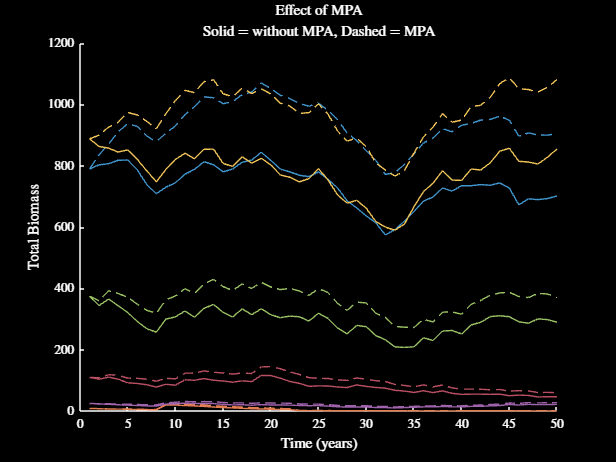

% ok, so here for those arbitrarily determined reefs above, I want to test
% out the effect of MPAs on the abundance - first set the parameters
rng(1)
var1 = [1, 4, 5, 6, 78, 30];
tMax = 50;
successVecCTMPA = cat(2, [0.65, 0.75], repmat(0.86, [1, 11]));
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsCTPre), 1, tMax - 1);
actionStruct.type = "MPA";
actionVec = zeros(1, length(conMatsCTPre{1}));
actionVec(var1) = 1;
actionStruct.actionVec = actionVec;
actionStruct.actionEffect = successVecCTMPA;
popInitTest = 50 * ones(length(conMatsCTPre{1}), 14);
actionStruct.type = "MPA";

% run without the MPA
popMatTest1 = baseMetapopModel(conMatsCTPre, areasCT, ...
        popInitCT, tMax, specStructCT, randStruct);

% run with the MPA
popMatTest2 = baseMetapopModel(conMatsCTPre, areasCT, ...
        popInitCT, tMax, specStructCT, randStruct, actionStruct);

% convert the results to biomasses
biomassMat1 = convertAgeClasses(popMatTest1, massVecCT);
biomassMat2 = convertAgeClasses(popMatTest2, massVecCT);

% plot the results
figure
hold on
for r = 1:length(var1)
    plot(biomassMat1(var1(r), :), 'Color', getColour(r))
    plot(biomassMat2(var1(r), :), '--', 'Color', getColour(r))
end
xlabel("Time (years)")
ylabel("Total Biomass")
title("Effect of MPA")
subtitle("Solid = without MPA, Dashed = MPA")
darkFig()

## Preliminary Coral Trout Simulations (Uniform Areas)

% IMPORTANT - some of the variables used in this early experiment are
% reassigned later, so the below code will likely produce different
% results (or maybe not work if the variables don't match idfk)

% begin by setting up the relevant parameters for the simulation
nRepsCTPre = 50;
tWarmup = 100;
tObs = 20;
tFinal = 50;
randStruct = struct();
randStruct.randType = "sequence";
nReefs = length(conMatsCTPre{1});
actionStruct.type = "MPA";
actionStruct.actionEffect = successVecCTMPA;
portPerfCTPre = zeros(nRepsCTPre, 7);
mpaSelCTPre = cell(1, nRepsCTPre);

% time stuff
tic

% loop over each run
for r = 1:nRepsCTPre

    % run the metapopulation model for the warmup period
    randStruct.sequence = randi(length(conMatsCTPre), 1, tWarmup - 1);
    popMatWarmup = baseMetapopModel(conMatsCTPre, [], ...
        popInitCT, tWarmup, specStructCT, randStruct);

    % run the metapopulation model for the observatory period
    randStruct.sequence = randi(length(conMatsCTPre), 1, tWarmup - 1);
    popMatObs = baseMetapopModel(conMatsCTPre, [], ...
        squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
        randStruct);

    % convert the age structured population trajectories into a single,
    % size class discounted sum
    biomassMat = convertAgeClasses(popMatObs, massVecCT);

    % run the decision making code to choose the MPAs for each of the
    % options, first calculating the weight = 1 and weight = 0 portfolios,
    % as these will contributed to the boundVals inputs for the following
    % runs
    boundVals = zeros(2, 2);
    mpaSelCTPre{r} = cell(1, 5);
    [mpaSelCTPre{r}{1}, boundVals(1, 2), boundVals(2, 2)] = applyMPT( ...
        biomassMat, 1, "discrete");
    [mpaSelCTPre{r}{5}, boundVals(1, 1), boundVals(2, 1)] = applyMPT( ...
        biomassMat, 0, "discrete");
    mpaSelCTPre{r}{2} = applyMPT(biomassMat, 0.75, "discrete", [], [], ...
        boundVals);
    mpaSelCTPre{r}{3} = applyMPT(biomassMat, 0.5, "discrete", [], [], ...
        boundVals);
    mpaSelCTPre{r}{4} = applyMPT(biomassMat, 0.25, "discrete", [], [], ...
        boundVals);
    mpaSelCTPre{r}{6} = rand(1, nReefs) < 0.3;
    mpaSelCTPre{r}{7} = zeros(1, nReefs);

    % note also that the computation time for the above is somewhat
    % intensive, so maybe could think about attempting to improve that

    % select a sequence of connectivity matrices, which will be the same
    % across all portfolio samples
    randStruct.sequence = randi(length(conMatsCTPre), 1, tFinal - 1);

    % run each of the models for the rest of the testing period -> yo -
    % need to make sure that I actually properly run each thing with the
    % same sequence of matrices, so that I can standardise across runs
    popMatCell = cell(1, length(mpaSelCTPre{r}));
    for m = 1:length(mpaSelCTPre{r})
        actionStruct.actionVec = mpaSelCTPre{r}{m};
        popMatCell{m} = baseMetapopModel(conMatsCTPre, [], ...
            squeeze(popMatObs(:, :, end)), tFinal, specStructCT, ...
            randStruct, actionStruct);
    end

    % evaluate the performance of each of the models using our objective
    % function
    for m = 1:length(mpaSelCTPre{r})
        portPerfCTPre(r, m) = objFuncMPA(popMatCell{m}, massVecCT);
    end

    % every 10 iterations print the time
    if mod(r, 10) == 0
        disp(r)
        toc
        currTime = toc;
    end

end

    10



Elapsed time is 2350.472873 seconds.


    20



Elapsed time is 4645.462353 seconds.


    30



Elapsed time is 6939.064478 seconds.


    40



Elapsed time is 8855.504279 seconds.


    50



Elapsed time is 10559.803334 seconds.


% at some point, I should set up an example for which picking out the
% optimal portfolio is very obvious, and check that my above applyMPT()
% code is working

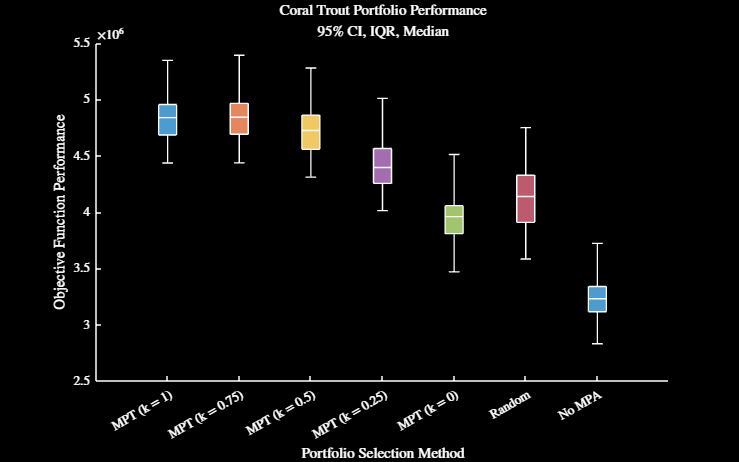

% now, want to examine the results of the above experiments - maybe a
% classic boxplot would be effective
names = ["MPT (k = 1)", "MPT (k = 0.75)", "MPT (k = 0.5)", ...
    "MPT (k = 0.25)", "MPT (k = 0)", "Random", "No MPA"];
figure
myBoxPlot(portPerfCTPre, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Performance")
title("Coral Trout Portfolio Performance")
figRect(1, 1.2)
saveFig("CT Portfolio Performance")
darkFig()

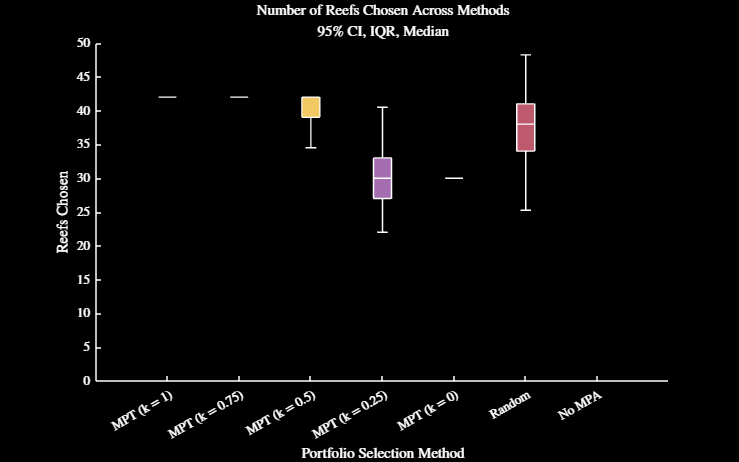


% note the difference before in performance before I added the correct
% scaling in the objective function - before, it was clear that the
% variance being minimised was a big deal and hence the expected returns
% were much lower the second the weight < 1

% make a boxplot of the number of reefs chosen
numReefsChosen = zeros(size(portPerfCTPre));
for m = 1:size(portPerfCTPre, 2)
    for r = 1:size(portPerfCTPre, 1)
        numReefsChosen(r, m) = sum(mpaSelCTPre{r}{m});
    end
end
figure
myBoxPlot(numReefsChosen, names)
xlabel("Portfolio Selection Method")
ylabel("Reefs Chosen")
title("Number of Reefs Chosen Across Methods")
figRect(1, 1.2)
saveFig("CT Number Reefs Chosen")
darkFig()

% next, let's look at heatmaps of the selections bewteen models, however
% to do this, I will need match up the centroids from the CT data to those
% of the reefs

% first, let's count up the proportion of times each reef is selected
% across all the trials
nReefsCTFullPre = length(conMatsCTPre{1});
propSelect = zeros(nReefsCTFullPre, length(mpaSelCTPre{1}));
for r = 1:nRepsCTPre
    for m = 1:length(mpaSelCTPre{r})
        propSelect(:, m) = propSelect(:, m) + mpaSelCTPre{r}{m}';
    end
end

% normalise
propSelect = propSelect / nRepsCTPre;

% make some cool heatmaps :) (I will do this later because my brain is
% currently tired xd)

## Improving Mike's Code

% note that there used to be code here which was meant to help speed up the
% code for creating the coral trout connectivity matrices but it completely
% cooked it so I moved it to a script called improvingMikesCode.m

## Loading Final CT Data and Matching to Shapefile

% honestly I want to re - calculate the centroids, as I don't trust them
% currently
GBRShapeLL = calcCentroids(GBRShapeLL);

% grab some shit from the GBRShapeLL
nReefsGBR = length(GBRShapeLL);
centroidsGBR = zeros(nReefsGBR, 2);
for r = 1:nReefsGBR
    centroidsGBR(r, :) = GBRShapeLL(r).Centroid;
end

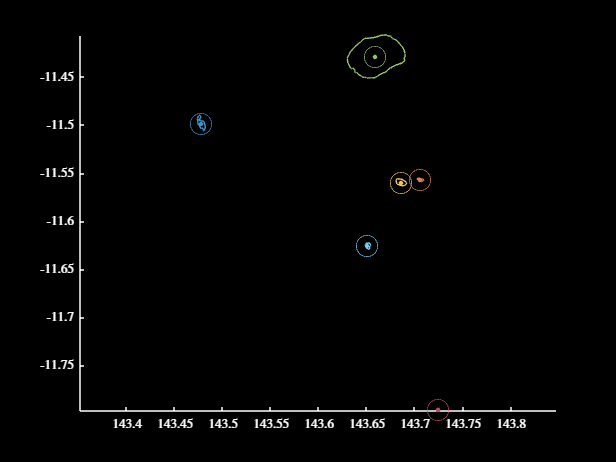

% check if the GBRShapeLL centroids themselves are actually matched up
% correctly
var1 = 400;
var2 = 405;
figure
hold on
for r = var1:var2
    plot(centroidsGBR(r, 1), centroidsGBR(r, 2), '.', 'Color', ...
        getColour(r - var1 + 1, var2 - var1 + 1), 'MarkerSize', 10)
    plot(GBRShapeLL(r).X, GBRShapeLL(r).Y, 'Color', ...
        getColour(r - var1 + 1, var2 - var1 + 1))
    plot(GBRShapeLL(r).Centroid(1), GBRShapeLL(r).Centroid(2), ...
        'o', 'Color', getColour(r - var1 + 1, var2 - var1 + 1), ...
        'MarkerSize', 16)
end
axis equal
darkFig()


% these all look fine so far

% load in the data
load coralTroutConnectivityData.mat

% reassign the centroid variable
centroidsCTFull = centroid;

% remove any rows with NaNs
nansInd = zeros(length(centroidsCTFull), 1);
for i = 1:length(centroidsCTFull)
    if sum(isnan(centroidsCTFull(i, :))) > 0
        nansInd(i) = 1;
    end
end
centroidsCTFull = centroidsCTFull(nansInd == 0, :);

% convert the matrices to sparse storage, remove the extra column and sort
% by latitude
conMatsCTFull = conMatsCoralTrout;
conMatsCTNames = conMatsCoralTroutNames;
nMatsCT = length(conMatsCTFull);
[~, sortLatCT] = sort(centroidsCTFull(:, 2));
centroidsCTFull = centroidsCTFull(sortLatCT, :);
for m = 1:nMatsCT

    % assign the thingos
    conMatsCTFull{m} = sparse(conMatsCTFull{m}(:, 1:(end - 1)));
    conMatsCTFull{m} = conMatsCTFull{m}(nansInd == 0, nansInd == 0);
    conMatsCTFull{m} = conMatsCTFull{m}(sortLatCT, sortLatCT);
    nReefsCTFull = size(conMatsCTFull{1}, 1);

    % because Mike's code makes me want to rip my hair out I need to remove
    % any NaNs leftover from his code, and just replace them with zeros
    nansMask = isnan(conMatsCTFull{m});
    conMatsCTFull{m}(nansMask) = 0;

end

% remove old variables
clear conMatsCoralTrout conMatsCoralTroutNames centroid

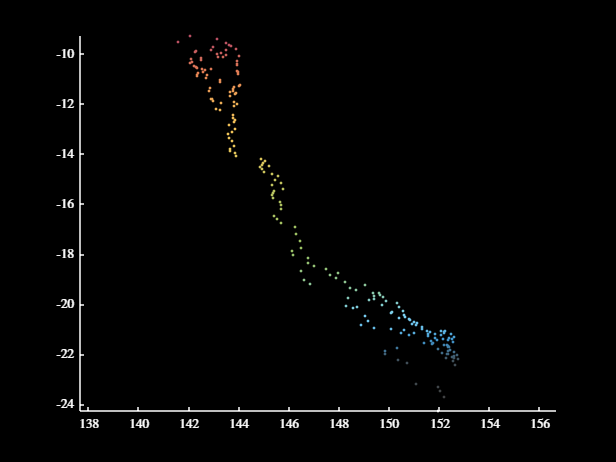

figure
hold on
for r = 1:10:nReefsCTFull
    plot(centroidsCTFull(r, 1), centroidsCTFull(r, 2), '.', 'Color', ...
        getColour(r, nReefsCTFull))
end
axis equal
darkFig()

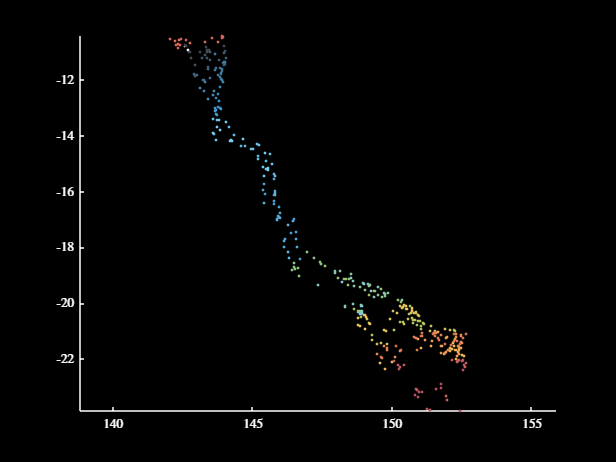

figure
hold on
for r = 1:10:nReefsGBR
    plot(centroidsGBR(r, 1), centroidsGBR(r, 2), '.', 'Color', ...
        getColour(r, nReefsGBR))
end
axis equal
darkFig()

% check the row sums now
var1 = zeros(1, nMatsCT);
for m = 1:nMatsCT
    var1(m) = sum(sum(conMatsCTFull{m}, 2) > 1);
end
var2 = find(var1)

var2 =      3    14    22


var1(var2)

ans =      1     4     1



% great, looks like this has basically cleared up the row sums issue

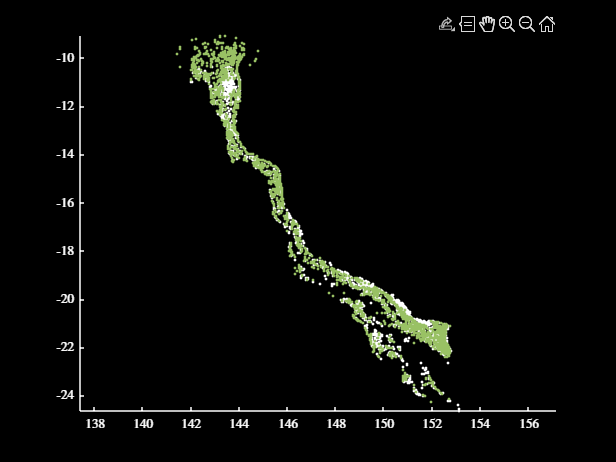

figure
hold on
plot(centroidsGBR(:, 1), centroidsGBR(:, 2), 'k.')
plot(centroidsCTFull(:, 1), centroidsCTFull(:, 2), '.', 'Color', ...
    getColour('g'))
axis equal
darkFig()

% figure out the smallest pairwise distance between the coral trout
% centroids
minCentDistCT = min(pdist(centroidsCTFull), [], "all")

minCentDistCT = 0.0019

test =          100         200         -20
         400        -300          10
         100         300        1000


var1 =    -20
  -300
   100


var2 =      3
     2
     1


var2 =      3
     2
     1


% re - write my code because dumb cunmt fuckinga bullshit piss fucker code
% isn't working
pairDists = pdist2(centroidsCTFull, centroidsGBR);
tol = 0.05;

% set up vectors to store the results
reefAssignCT = zeros(nReefsCTFull, 1);

% loop for all the reefs in centroidsCTFull, until we hit the minimum
% tolerance
for r = 1:nReefsCTFull

    % determine the current minimum distance, and the index it corresponds
    % to
    [currMinDist, currCTReef] = min(min(pairDists, [], 2));
    [~, currGBRReef] = min(pairDists(currCTReef, :));

    % if the current minimum distances is above the tolerance, break out of
    % the loop
    if currMinDist > tol
        break
    end

    % otherwise, let's make the assignment, and reassign the other pairwise
    % reefs
    reefAssignCT(currCTReef) = currGBRReef;
    pairDists(currCTReef, :) = 10^10;
    pairDists(:, currGBRReef) = 10^10;

end

% grab stuff from the shapeFile etc
nReefsCT = sum(reefAssignCT > 0);
ctr = 1;
GBRShapeCT = GBRShapeLL(nReefsCT);
for r = 1:nReefsCTFull
    if reefAssignCT(r) == 0
        continue
    end
    GBRShapeCT(ctr) = GBRShapeLL(reefAssignCT(r));
    ctr = ctr + 1;
end
centroidsCT = centroidsCTFull(reefAssignCT > 0, :);
areasCT = zeros(nReefsCT, 1);
for r = 1:nReefsCT
    areasCT(r) = GBRShapeCT(r).Shape_Area;
end

% also convert the matrices
conMatsCT = cell(1, nMatsCT);
for m = 1:nMatsCT
    conMatsCT{m} = conMatsCTFull{m}(reefAssignCT > 0, ...
        reefAssignCT > 0);
end

nReefsCT = 1903


% get rid of the old matrices
clear conMatsCTFull

% let's look at how many didn't get assigned, and look if any doubled up
nUnassigned = length(reefAssignCT) - sum(reefAssignCT > 0)

nUnassigned = 254

nDoubleUps = 2 * (length(reefAssignCT(reefAssignCT > 0)) ...
    - length(unique(reefAssignCT(reefAssignCT > 0))))

nDoubleUps = 0

clear nUnassigned nDoubleUps
unassigned = reefAssignCT == 0;
doubleUps = zeros(1, length(centroidsCT));
for r = 1:length(centroidsCT)
    if sum(reefAssignCT(r) == reefAssignCT) > 1 && reefAssignCT(r) > 0
        doubleUps(r) = 1;
    end
end

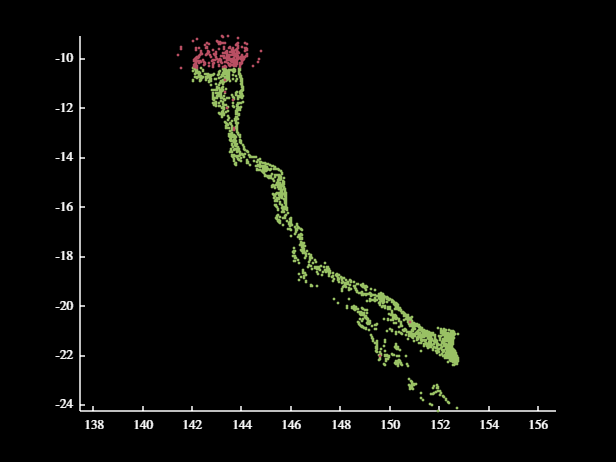

figure
hold on
plot(centroidsCTFull(reefAssignCT > 0, 1), ...
    centroidsCTFull(reefAssignCT > 0, 2), '.', 'Color', getColour('g'))
plot(centroidsCTFull(reefAssignCT == 0, 1), ...
    centroidsCTFull(reefAssignCT == 0, 2), '.', 'Color', getColour('r'))
axis equal
darkFig()

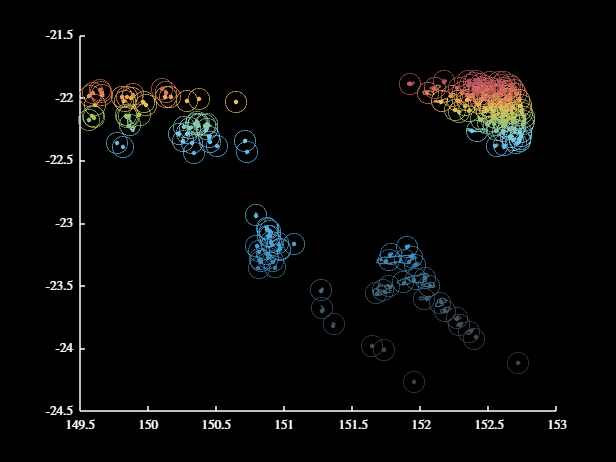

% plot just a subset of some of the things
figure
hold on
var1 = 1;
var2 = 200;
for r = var1:var2
    plot(centroidsCT(r, 1), centroidsCT(r, 2), '.', 'Color', ...
        getColour(r - var1 + 1, var2 - var1 + 1), 'MarkerSize', 10)
    plot(GBRShapeCT(r).X, GBRShapeCT(r).Y, 'Color', ...
        getColour(r - var1 + 1, var2 - var1 + 1))
    plot(GBRShapeCT(r).Centroid(1), GBRShapeCT(r).Centroid(2), ...
        'o', 'Color', getColour(r - var1 + 1, var2 - var1 + 1), ...
        'MarkerSize', 16)
end
darkFig()

% saveCoolFig("centroidCheck")

% plot the new shapefile
% figure
% plotGBRShape(GBRShapeCT)
% darkFig()